# Linear Control Design II - Group Work Problem Module 15 Solution

## Description

**Problem 1** Consider the $2^{\mathrm{nd}}$ order SISO system


$$\dot{\mathbf{x}}=\mathbf{A}\mathbf{x} + \mathbf{B}u$$


where:


$$\mathbf{A} = \left[
 \begin{array}{rr}
  -1 & 1\\
  0 & 2
 \end{array}\right]\qquad
 \mathbf{B} = \left[
 \begin{array}{r}
  1\\
  0
 \end{array}\right]$$


The optimal control law 


$$u = -\mathbf{K}\mathbf{x}$$


is to be designed by minimizing the performance index $J$ given by:


$$J = \int\limits_0^\infty \left( \mathbf{x}^\text{T}\mathbf{R}_1\mathbf{x} + u^\text{T}\mathbf{R}_2u \right)dt$$


Where:


$$ \mathbf{R}_1 = \left[
 \begin{array}{rr}
  1 & 0\\
  0 & 1
 \end{array}\right]\qquad
 \mathbf{R}_2 = \left[
 \begin{array}{r}
  1  
 \end{array}\right]$$


- Show analytically that the system cannot be stabilized by any gain matrix $\mathbf{K}$.

- Draw a block diagram of the system and use it to explain your results.

- Use the Matlab function `lqr` to design the optimal controller. Discuss the numerical results in relation to your analytical findings.

**Solution****:**

By drawing the block diagram of the system or by calculating the controllability matrix of it like:


$$ \mathbf{Q}=\left[\mathbf{B}\quad \mathbf{AB}\right]
$$


 it can be seen that the system is not controllable. Thus, one cannot make an LQR (or any other state feedback regulator) for it.

Another approach is to try to find the eigenfrequencies of the closed loop system. Let $\mathbf{K}$ be the controller gain:


$$\mathbf{K} = \left[ k_1 \quad k_2 \right]$$


Then:


$$\text{det}(\lambda\mathbf{I}-(\mathbf{A}-\mathbf{BK})) = (\lambda+1+k_1)(\lambda-2) = 0$$


which implies that the closed loop poles are at $\lambda_1=-1-k_1$ and $\lambda_2=2$. The second pole is the right half plane and cannot be moved by the controller i.e. its expression does not depend on $k_1$ or $k_2$. Thus the regulator is unstable no matter what the value of $\mathbf{K}$ is.

If one, for example, does try to make an LQR controller and uses the weighting matrices:


$$ \mathbf{R_1} = \left[
 \begin{array}{rr}
  1 & 0\\
  0 & 1
 \end{array}\right]\qquad
 \mathbf{R_2} = \left[
 \begin{array}{r}
  1  
 \end{array}\right]$$


and Matlab function *K=lqr(A, B, R1, R2)* then the following result is obtained:


$$\mathbf{K}=\left[ \text{NaN} \quad \text{NaN} \right]$$


and the warning *Matrix is singular to working precision*.

**Problem 2**  Consider the $2^{\mathrm{nd}}$ order SISO system


$$ \dot{\mathbf{x}}=\mathbf{A}\mathbf{x} + \mathbf{B}u$$


where:


$$\mathbf{A} = \left[
 \begin{array}{rr}
  0 & 1\\
  0 & -1
 \end{array}\right]\qquad
 \mathbf{B} = \left[
 \begin{array}{r}
  0\\
  1
 \end{array}\right]
$$


The optimal control law 


$$u = -\mathbf{K}\mathbf{x}$$


is to be designed by minimizing the performance index $J$ given by:


$$J = \int\limits_0^\infty \left( \mathbf{x}^\text{T}\mathbf{R}_1\mathbf{x} + u^\text{T}\mathbf{R}_2u \right)dt$$


where:


$$\mathbf{R}_1 = \left[
 \begin{array}{rr}
  1 & 0\\
  0 & 1
 \end{array}\right]\qquad
 \mathbf{R}_2 = \left[
 \begin{array}{r}
  1  
 \end{array}\right]$$


- Determine the optimal feedback gain matrix $\mathbf{K}$ for this system.

**Solution****:**

The optimal gain for this exercise is obtained by using the Matlab routine K=lqr(A, B, R1, R2). One can also, in this simple case, solve the Riccati equation directly:


$$\mathbf{A}^\text{T}\mathbf{P} + \mathbf{PA} - \mathbf{PBR_2^{-1}B^\text{T}P} + \mathbf{R_1} = 0$$


% System Matrices
A = [0 1;0 -1];
B = [0;1];
C = [1 1];
D = 0;

% Weighting Matrices
R1 = [1 0;0 1];
R2 = 1;

% Compute the optimal gain
K = lqr(A, B, R1,R2);
disp('Optimal gain matrix')

Optimal gain matrix


disp(K);

            1            1




[K,P,E] = lqr(A, B, R1,R2);
disp('Solution of the algebraic Riccati equation')

Solution of the algebraic Riccati equation


disp(P);

            2            1
            1            1



disp('Closed loop eigenvalues')

Closed loop eigenvalues


disp(E);

           -1
           -1



The solution is:


$$ \mathbf{P} = \left[\begin{array}{cc}
  2 & 1\\ 1 & 1
 \end{array}\right]$$


from which the optimal gain matrix $\mathbf{K}$ can be computed:


$$ \mathbf{K} = \left[ 1 \right] \left[0\quad 1\right] \left[
 \begin{array}{cc}
  2 & 1\\1 & 1
 \end{array}\right] = \left[1 \quad 1\right]$$


Explicitly, the optimal control feedback law is:


$$ u=-\mathbf{K}x = -x_1-x_2$$


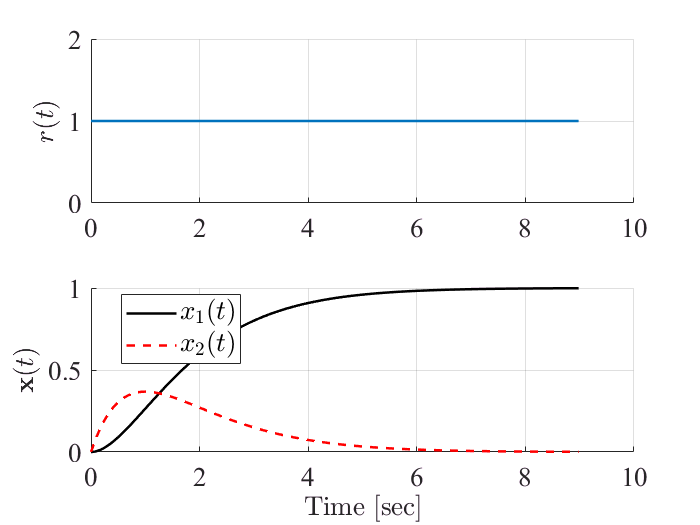

% Plot state responses: connect feedback loop
Ak = A - B*K;
k1 = K(1);
k2 = K(2);
Bk = B*k2;

[y,x,t] = step(Ak,Bk,C,D);

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
u = square(2*pi*0.05*t);
plot(t,u,'LineWidth',1.5);
ylabel('$r(t)$','FontName','times','FontSize',16,'Interpreter','latex')

h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,[1 0]*x','-k',t,[0 1]*x','--r','LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'Interpreter','latex')
l = legend('$x_1(t)$','$x_2(t)$','Location','Best');
set(l,'FontName','times','FontSize',16,'Interpreter','latex');

**Problem 3**  Consider the $3^{\mathrm{rd}}$ order SISO system


$$\dot{\mathbf{x}} =\mathbf{A}\mathbf{x} + \mathbf{B}u\\
 y = \mathbf{C}\mathbf{x} + \mathbf{D}u$$


where:


$$\mathbf{A} = \left[
 \begin{array}{rrr}
  0 & 1 & 0\\
  0 & 0 & 1\\
  0 & -2 & -3
 \end{array}\right]\qquad
 \mathbf{B} = \left[
 \begin{array}{r}
  0\\
  0\\
  1
 \end{array}\right]
 \qquad
 \mathbf{C} = \left[
 \begin{array}{rrr}
  1 & 0 & 0
 \end{array}\right]
 \qquad
 \mathbf{D} = \left[
 \begin{array}{r}
  0
 \end{array}\right]$$


The performance index $J$ is given by:


$$ J = \int\limits_0^\infty \left( \mathbf{x}^\text{T}\mathbf{R}_1\mathbf{x} + u^\text{T}\mathbf{R}_2u \right)dt$$


where:


$$\mathbf{R}_1 = \left[
 \begin{array}{rrr}
  100 & 0 & 0\\
  0 & 1 & 0\\
  0 & 0 & 1
 \end{array}\right]\qquad
 \mathbf{R}_2 = \left[
 \begin{array}{r}
  0.01  
 \end{array}\right]$$


- Why would one choose the matrix elements of the state weighting matrix in this way?

  Assume that the following control law is designed


$$u=k_1(r-x_1) - (k_2x_2+k_3x_3)$$


where $r$ is the reference input to the system.

        2. What control objective is fulfilled with the given feedback law?

        3. Determine the optimal steady state feedback gain matrix $\mathbf{K}$ for this system.

        4. Plot the step response of the closed loop system.

**Solution****:**

The output of this system is state $x_1$, which is also the main objective of the control strategy. The other states are secondary. This is the reason for the structure of the control system and why the weighting matrix has been selected in the suggested way. Making the top left element of $\mathbf{R_1}$ equals 100 i.e. $\mathbf{R}_1(1,1)=100$ ensures that this state has a faster response. Remember that the law for weighting the states is**:**


$$\mathbf{R_1}(i,i) = \frac{1}{(t_1-t_0)\max\left[x_i(t)\right]^2}$$


In the problem case, $t_1-t_0=1$. $x_i(t)$ is the state error with respect to the selected nominal operational point i.e. $\Delta x = x-x_0$. In this particular case, $x_0=0$ is the linearization point. If $\Delta x_1$ needs to be small then $\mathbf{R_1}(1,1)$ has to be large.

The optimal control matrix can be found using the Matlab routine *K = lqr(A, B, R1, R2)*:

% Determination of optimal gain for 2X2 system

% System Matrices
A = [0 1 0;0 0 1;0 -2 -3];
B = [0;0;1];
C = [1 0 0];
D = 0;

% Weighting Matrices
R1 = [100 0 0;0 1 0;0 0 1];
R2 = [0.01];

% Compute the optimal gain
K = lqr(A, B, R1,R2);
disp('Optimal gain matrix')

Optimal gain matrix


disp(K);

          100        53.12       11.671




$$ \mathbf{K} = \left[
 \begin{array}{ccc}
  k_1&k_2&k_3
 \end{array}\right]
 = \left[
 \begin{array}{ccc}
  100 & 53.12 & 11.6711
 \end{array}\right]$$


Equivalently one can use the Matlab command *[K P E] = lqr(A,B,C,D)*, where $\mathbf{P}$ is the matrix in the Riccati equation and $\mathbf{E}$ are the eigenvalues of the system.

[K,P,E] = lqr(A, B, R1,R2);
disp('Solution of the algebraic Riccati equation')

Solution of the algebraic Riccati equation


disp(P);

        55.12       14.671            1
       14.671       7.0267       0.5312
            1       0.5312      0.11671



disp('Closed loop eigenvalues')

Closed loop eigenvalues


disp(E);

      -10.243 +          0i
      -2.2141 +     2.2047i
      -2.2141 -     2.2047i



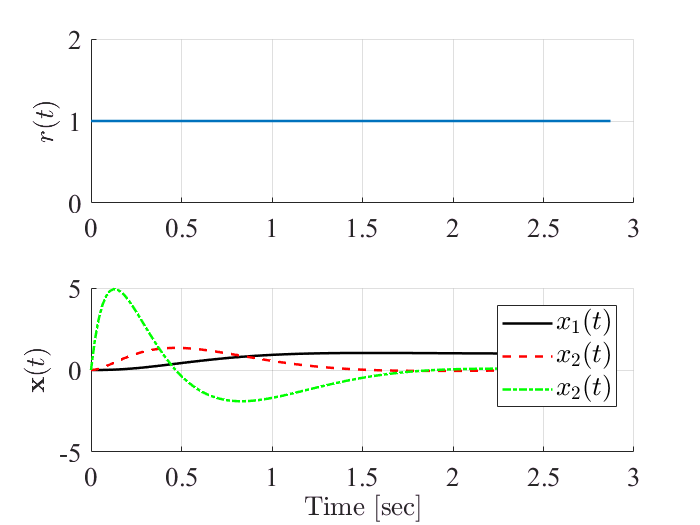

% Plot state responses: connect feedback loop
Ak = A - B*K;
k1 = K(1);
k2 = K(2);
k3 = K(3);
Bk = B*k1;

[y,x,t] = step(Ak,Bk,C,D);

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
u = square(2*pi*0.05*t);
plot(t,u,'LineWidth',1.5);
ylabel('$r(t)$','FontName','times','FontSize',16,'Interpreter','latex')

h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(t,[1 0 0]*x','-k',t,[0 1 0]*x','--r',t,[0 0 1]*x','-.g','LineWidth',1.5)
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')
ylabel('$\mathbf{x}(t)$','FontName','times','FontSize',16,'Interpreter','latex')
l = legend('$x_1(t)$','$x_2(t)$','$x_2(t)$','Location','NorthEast');
set(l,'FontName','times','FontSize',16,'Interpreter','latex');

The optimal LQR gains are optimal independent of how they are used in the regulator. Thus the unusual configuration of the control system configuration used in this problem has no effect on the optimal gains found: an optimal solution is optimal.

The step response can be found using the Matlab command *[x, y, t] = step(AK, Bk1, C, D)* where *AK=A-B*K* and *Bk1 = B*k1*. The last statement ensures that the input and feedback to the system is via the state $x_1$,  which is that state that is to be controlled most accurately.